# *******************               Antenna Array Processing               *******************

## **************                                                   HW9                                                   **************

***********************************       Mohammadreza Arani         :::::::::::::         810100511       ***********************************

*****************************************************************       1401/09/20       *****************************************************************    

clear; clc; close all;

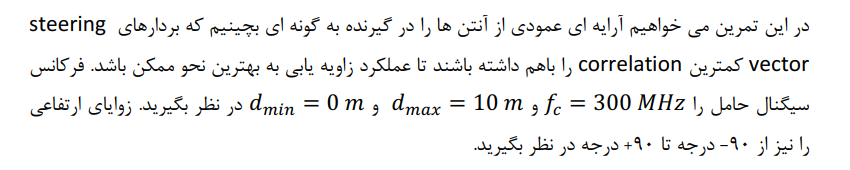

## Initialization:

theta = -90:0.1:90;

d_min = 0;
d_max = 10;
fc =    300e+06; % 300MHz
c = 3e+08;%Speed in Air

Lambda =  c/fc;% Lambda*fc = c => Lambda = c/fc
K = 2*pi/Lambda;


## Part 1)

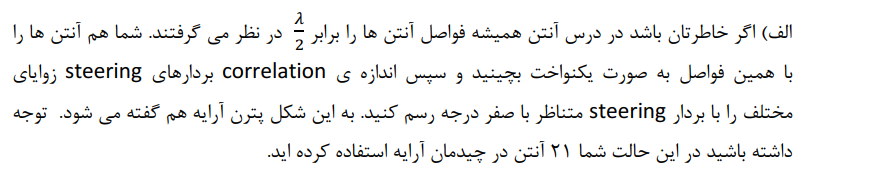

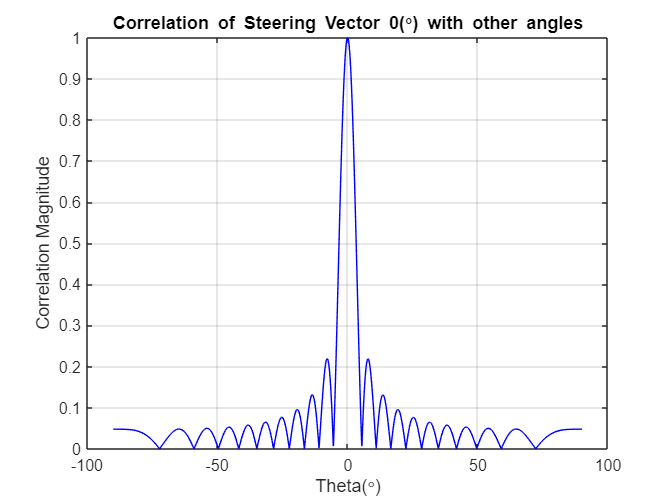


D = (d_min:Lambda/2:d_max)'; % Antenna Positions <Uniform Linear Array> - d = Lambda/2
M = length(D);

% Using Given Code of steering.m

MAP = exp(1j*K*D*sind(theta)) ;  % Matrix of Steering Vectors 

zav=0;

a=exp(1j*K*D*sind(zav)); % Steering Vector corresponding to 0 degrees

g=abs(a'*MAP); % Inner Product of  steering Vector for 0 degrees and MAP
g=g/max(g); % Normalization of g
plot(theta,(g),'b');
grid on
title("Correlation of Steering Vector 0(\circ) with other angles")
xlabel("Theta(\circ)")
ylabel("Correlation Magnitude")

% We have Used 21 elements of Antenna! --> Above Figure is called:
% Antenna
% Pattern

## Part 2)

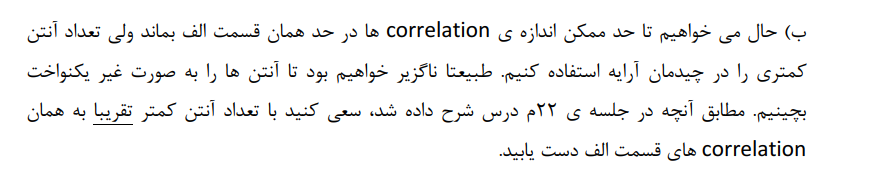

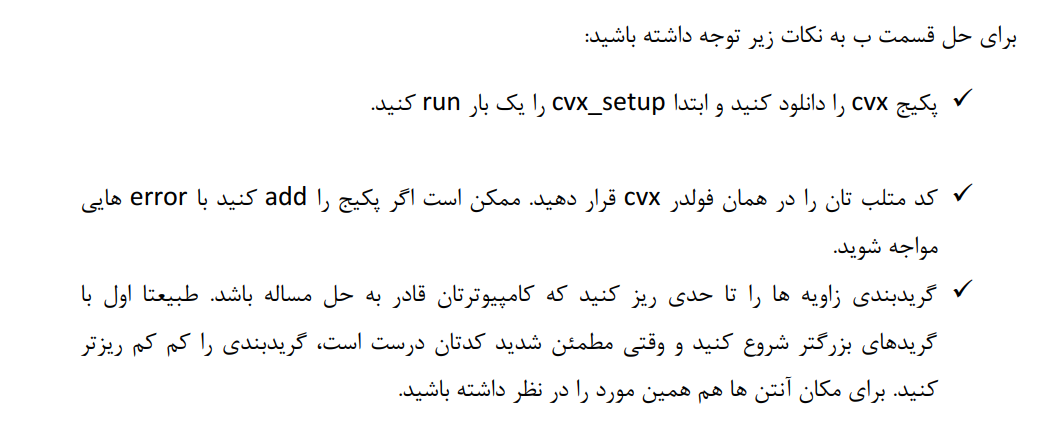

% cvx_setup  --- >  DOne Before
% CVX Path has been Added!

% Starting the algorithm:

A  = exp(1j*K*D*sind(theta));

 cvx_begin 


        variable W(M);
        variable t;
        %variable Z(n,n) symmetric;

        minimize( t ) % Minimize a Convex Function
        
        subject to % Our Constraints:
            ones(1,M)*W == 1;
            abs(W'*A)        <= t;

  cvx_end

 
Calling SDPT3 4.0: 7204 variables, 1823 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 1823
 dim. of socp   var  = 5402,   num. of socp blk  = 1801
 dim. of linear var  = 1801
 dim. of free   var  =  1 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.4e+03|1.1e+03|6.6e+06| 3.642686e-11  0.000000e+00| 0:0:00| spchol  1  1 
 1|0.968|0.978|7.6e+01|2.4e+01|2.1e+05|-1.055986e+00 -8.399412e+01| 0:0:01| spchol  1  1 
 2|0.957|0.885|3.3e+00|2.8e+00|9.3e+03|-8.978524e-03 -8.66



  Cost = cvx_optval;
  W_answers = W;




## See the CVX Results:

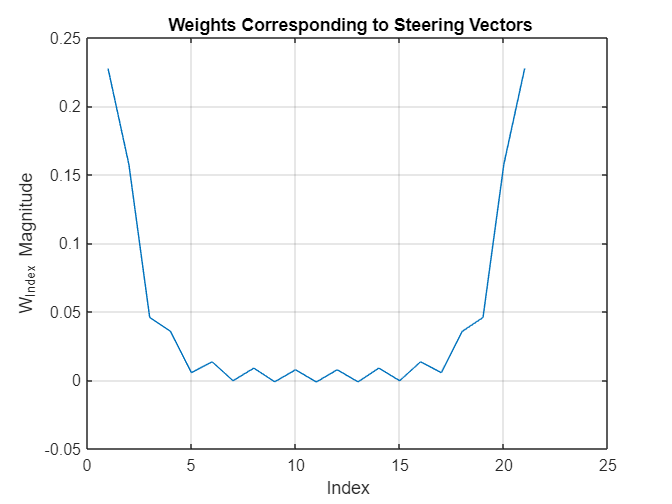


figure(2)

plot((1:length(W_answers)),W_answers);
grid on
title(" Weights Corresponding to Steering Vectors")
xlabel("Index")
ylabel("W_{Index} Magnitude")

## See the Corresponding Pattern:

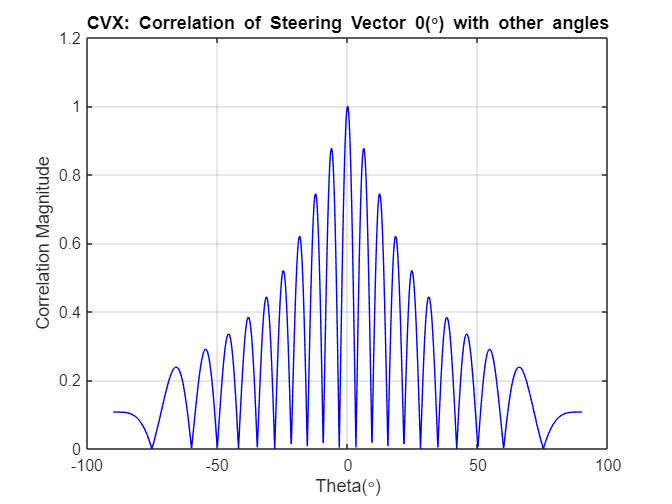

MAP = exp(1j*K*D*sind(theta)) ;  % Matrix of Steering Vectors 

zav=0;

plot(theta,abs(W'*A),'b');
grid on
title("CVX: Correlation of Steering Vector 0(\circ) with other angles")
xlabel("Theta(\circ)")
ylabel("Correlation Magnitude")

## New CVX Problem:             <Over place of elements>

First distribute many points over y-axis and then choose those giving us the best pattern!  --- >>  Best Pattern is a pattern in which we see a delta-shaped beam.

D_init = linspace(d_min, d_max,1e2 )';
P = length(D_init); % a random large number -->> Number of elements in a dense array!


Max_poss_deg = asind(Lambda/d_max) ;
Theta_important = theta((theta > Max_poss_deg) | (theta < -Max_poss_deg) ); % Choose those Thetas that make the main beam! 
A_new = exp(1j*K*D_init*sind(Theta_important)); % New MAP Matrix




 cvx_begin 


        variable W(P);
        variable t;
        

        minimize( t ) % Minimize a Convex Function  
        
        subject to % Our Constraints:
            ones(1,P)*W          == 1;
            abs(W'*A_new)        <= t;
            W                    >= 0;
            W                    <= 1;
            

  cvx_end

 
Calling SDPT3 4.0: 6945 variables, 1787 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 1787
 dim. of socp   var  = 5058,   num. of socp blk  = 1686
 dim. of linear var  = 1886
 dim. of free   var  =  1 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.3e+03|5.9e+01|7.2e+06| 8.685620e+03  0.000000e+00| 0:0:00| spchol  1  1 
 1|0.976|0.810|5.4e+01|1.1e+01|3.0e+05| 8.229289e+03 -6.923182e+01| 0:0:01| spchol  1  1 
 2|0.795|0.290|1.1e+01|8.1e+00|1.3e+05| 6.931789e+03 -1.77

## Choose  (k) Best Weights:

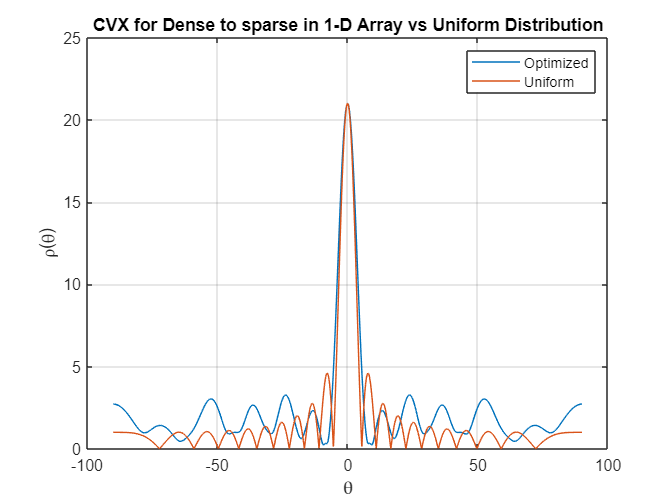


% Find k largest elements of array: 
% [B,I] = maxk(___) finds the indices of the largest k values of A and returns them in I.
k = M;
[W_answers_dense , W_Indexes ] = maxk( W , k )  ; 


D_dense_Chosen = D_init(W_Indexes);

Theta_test = 0;


Map_new = exp(1j*K*D_dense_Chosen*sind(theta));
% Map_new = Map_new./repmat(sqrt(sum(abs(Map_new).^2)),K,1);


a_new = (exp(1j*K*D_dense_Chosen*sind(Theta_test)));

Corr_Final = abs(a_new'*Map_new); % Correlation of New MAP with the Chosen Positions

figure(3)

plot(theta, Corr_Final);

grid on
xlabel('\theta')
ylabel('\rho(\theta)')
title("CVX for Dense to sparse in 1-D Array vs Uniform Distribution")

hold on

plot(theta, g*max(Corr_Final));

legend("Optimized","Uniform")

## Try with more number of elements:

D_init = linspace(d_min, d_max,1e3 )';
P = length(D_init); % a random large number -->> Number of elements in a dense array!


Max_poss_deg = asind(Lambda/d_max) ;
Theta_important = theta((theta > Max_poss_deg) | (theta < -Max_poss_deg) ); % Choose those Thetas that make the main beam! 
A_new = exp(1j*K*D_init*sind(Theta_important)); % New MAP Matrix




 cvx_begin 

        variable W(P);
        variable t;
        

        minimize( t ) % Minimize a Convex Function  
        
        subject to % Our Constraints:
            ones(1,P)*W          == 1;
            abs(W'*A_new)        <= t;
            W                    >= 0;
            W                    <= 1;
            

  cvx_end

 
Calling SDPT3 4.0: 8745 variables, 2687 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 2687
 dim. of socp   var  = 5058,   num. of socp blk  = 1686
 dim. of linear var  = 3686
 dim. of free   var  =  1 *** convert ublk to lblk
 number of dense column in A = 2
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.9e+03|7.7e+01|2.7e+07| 1.214249e+05  0.000000e+00| 0:0:03| spchol  1  1 
 1|0.978|0.820|6.4e+01|1.4e+01|3.0e+06| 1.163489e+05 -8.880441e+01| 0:0:06| chol  1  1 
 2|0.124|0.038|5.6e+01|1.4e


% Find k largest elements of array: 
% [B,I] = maxk(___) finds the indices of the largest k values of A and returns them in I.
k = M;
[W_answers_dense , W_Indexes ] = maxk( W , k )  ; 


D_dense_Chosen = D_init(W_Indexes);

Theta_test = 0;


Map_new = exp(1j*K*D_dense_Chosen*sind(theta));
% Map_new = Map_new./repmat(sqrt(sum(abs(Map_new).^2)),K,1);


a_new = (exp(1j*K*D_dense_Chosen*sind(Theta_test)));

Corr_Final = abs(a_new'*Map_new); % Correlation of New MAP with the Chosen Positions

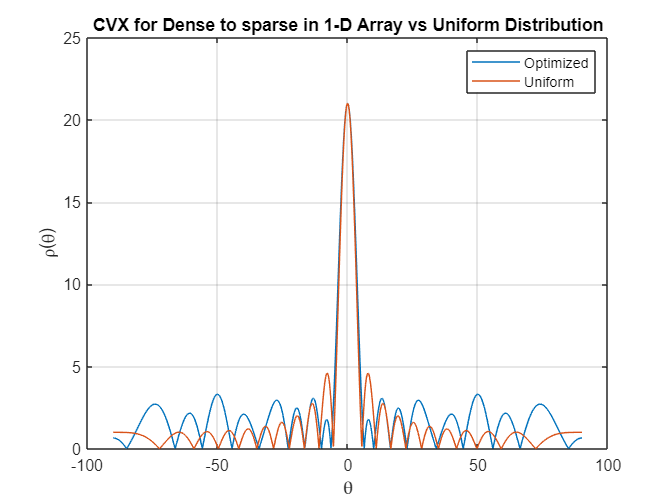

close all
figure(4)

plot(theta, Corr_Final);

grid on
xlabel('\theta')
ylabel('\rho(\theta)')
title("CVX for Dense to sparse in 1-D Array vs Uniform Distribution")

hold on

plot(theta, g*max(Corr_Final));

legend("Optimized","Uniform")

## Antenna Positions:

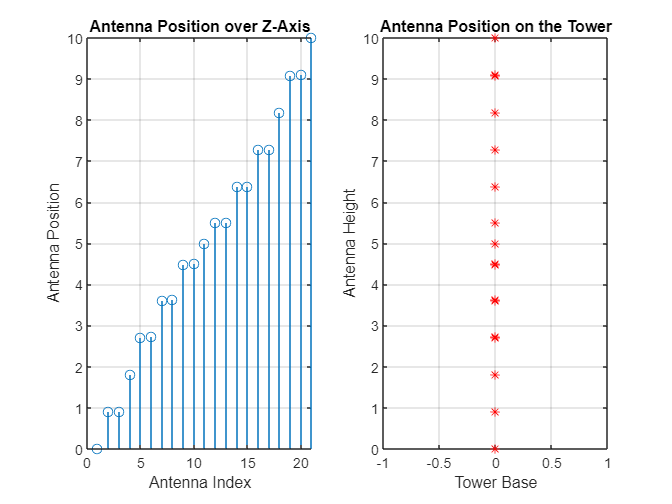


figure(6)
subplot(1,2,1)
stem(sort(D_init(W_Indexes)))
grid on
xlabel("Antenna Index")
ylabel("Antenna Position")
title("Antenna Position over Z-Axis")
subplot(1,2,2)
plot(zeros(1,length(W_Indexes)) , D_init(W_Indexes)  , 'r*')
grid on
title("Antenna Position on the Tower")
xlabel("Tower Base")
ylabel("Antenna Height")